clear;

Definimos los vectores 


$$symY = [y1 \ y2  \ y3 \ ...  \ yn] \\
symU = [u1 \ u2 \ u3  \ ... \ un]$$


N = 20;
% 
symY = SymsVector('y',N);
symU = SymsVector('u',N);

# Creamos la ecuacion que queremos estudiar

Primero creamos la condición inicial

xi = -1; xf = 1;
xline = linspace(xi,xf,N);
Y0 = 2+2*cos(pi*xline)';

Veamos Y0 graficamente.

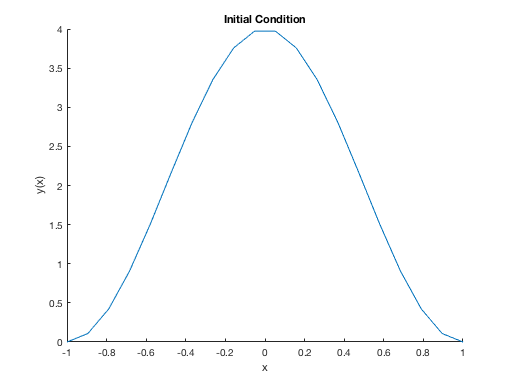

clf
line(xline,Y0)
xlabel('x')
ylabel('y(x)')
title('Initial Condition')

Crearemos ahora la expresion $\dot{Y} = f(t,X,U)$

s = 0.8;
A = -fl_rigidity_sym(s,1,N);
%  
a = -0.3; b = 0.5;
B = construction_matrix_B(xline,a,b);
% F(t,X,U)
Fsym  = A*symY + B*symU;

Para crear un objeto ode necesitamos indicarle como minimo los parametros F, Y y U. Si no se indican Y0  = zeros() y T = 1

T = 5;
odeEqn = ode(Fsym,symY,symU,'Y0',Y0,'T',T);

Veamos su comportamiento libre

%% U = zeros() por defecto
solve(odeEqn)
odeEqn.Y

ans =          0    0.1084    0.4217    0.9061    1.5090    2.1652    2.8034    3.3546    3.7589    3.9727    3.9727    3.7589    3.3546    2.8034    2.1652    1.5090    0.9061    0.4217    0.1084         0
    0.0624    0.2029    0.5083    0.9658    1.5315    2.1458    2.7427    3.2580    3.6359    3.8357    3.8357    3.6359    3.2580    2.7427    2.1458    1.5315    0.9658    0.5083    0.2029    0.0624
    0.1153    0.2820    0.5839    1.0187    1.5508    2.1264    2.6851    3.1670    3.5203    3.7071    3.7071    3.5203    3.1670    2.6851    2.1264    1.5508    1.0187    0.5839    0.2820    0.1153
    0.1601    0.3490    0.6493    1.0649    1.5667    2.1070    2.6303    3.0812    3.4117    3.5863    3.5863    3.4117    3.0812    2.6303    2.1070    1.5667    1.0649    0.6493    0.3490    0.1601
    0.1981    0.4057    0.7057    1.1048    1.5794    2.0873    2.5779    3.0001    3.3094    3.4728    3.4728    3.3094    3.0001    2.5779    2.0873    1.5794    1.1048    0.7057    0.4057

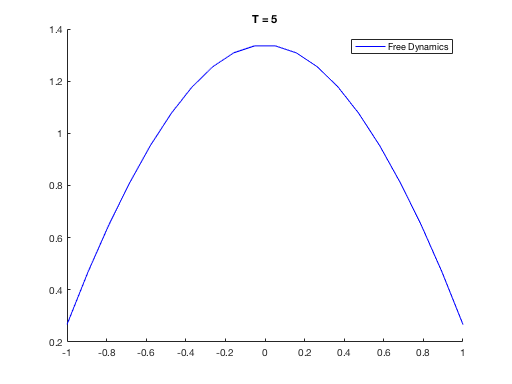

clf
line(xline,odeEqn.Y(end,:),'Color','blue')
legend('Free Dynamics')
title(['T = ',num2str(T)])

# Creamos el Funcional objectivo

Primero definimos un target 

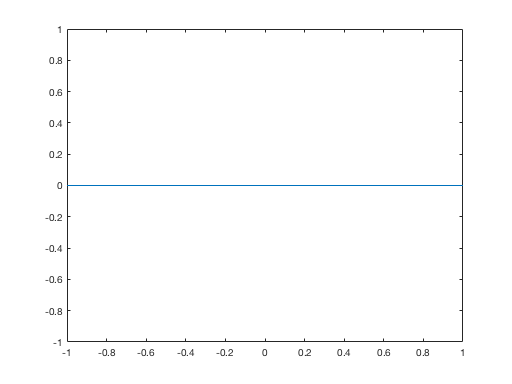

YT = 0.0*sin(pi*xline)';
%
plot(xline,YT)

Definimos el funcional como:


$$J(t,Y,U) = \Psi(t,X(T)) + \int_{0}^{T} L(t,Y,U) dt $$


En ese caso


$$J(t,Y,U) = (Y(T) - Y(t) )^2 + 0.001\int_{0}^{T} U(t)^2 dt$$


symPsi  = (YT - symY).'*(YT - symY);
symL    = 0.001*(symU.'*symU);

Jfun = Functional(symPsi,symL,symY,symU);

# Creamos Problema de Control

iCP1 = ControlProblem(odeEqn,Jfun,'T',5);

%% Solve Gradient

DescentParameters = {'MiddleStepControl',true,'InitialLengthStep',2.0};
Gradient_Parameters = {'maxiter',10,'DescentParameters',DescentParameters};
%
GradientMethod(iCP1,Gradient_Parameters{:})



%tol = 1.0;
%DescentParameters = {'MiddleStepControl',true,'InitialLengthStep',5.0};
%
%GradientMethod(iCP1,'tol',tol,'DescentParameters',DescentParameters,'graphs',true)
% Several ways to run
% GradientMethod(iCP1)
% GradientMethod(iCP1,'DescentParameters',DescentParameters)
% GradientMethod(iCP1,'DescentParameters',DescentParameters,'graphs',true)

% iCP1.ode

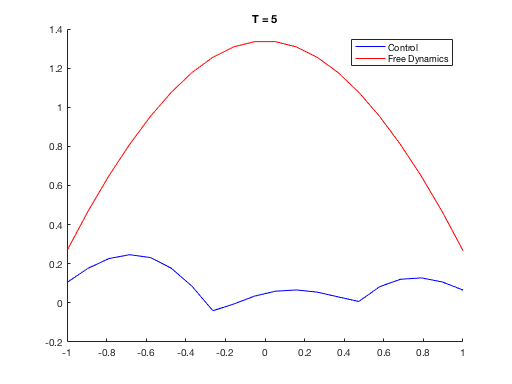

clf
line(xline,iCP1.ode.Y(end,:),'Color','blue')
line(xline,odeEqn.Y(end,:),'Color','red')
legend({'Control','Free Dynamics'})
title(['T = ',num2str(T)])

% comparar si evolu
% animation(iCP1.ode,'YLim',[-1,4],'xx',1.0)
% animation(odeEqn,'YLim',[-1,4],'xx',1.0)
